## [COM3240] Lab 6: Reinforcement Learning with ANNs

### **Overview**

In the previous lab you were given a simple reinforcement learning scenario. However, it is possible to implement your algorithm on an ****Artificial Neural Network (ANN)**. **

The key idea is that ****ANNs are universal function approximators****. You will use them to create a function where the input is the state and the output the Q-value of each action. In this case, you do not need to use a table to retain the Q-values. This is especially advantageous when you deal with problems with a large state and action space.

### Implementing the monkey scenario with an ANN

In the previous lab you were given a simple reinforcement learning scenario. It is possible to implement your algorithm on an Artificial Neural Network (ANN). To do so, you need to create a representation of the two images as an input vector (say a column vector 2x1; for instance [1 0]’ for Ballon and [0 1]’ or bicycle. Then you have to use a 2x2 weight matrix producing a 2x1 output vector. Use this vector as an input to a sigmoid function and call this result your output V (firing rate of the output (action) neurons). Say for instance that position V(1,1) represents the Q value of Green and V(2,1) represents the Q value of Red.

### How do the Q-values change?

In this setup, the Q-values are updated in an indirect way by modifying the synaptic weights. It turns out that a hebbian rule with a reward-dependent factor allows us to modify the weights appropriately: 


$$$\Delta w_{i,j} =  \eta\left[r-Q(s,i)\right]x_ix_j^s$,
$$


where $$r$$ is the reward, $$Q(s,i)$$ the Q-value of state $$s$$ and action $$i$ $ (the selected action), $$x_i$$ the activity of the neuron that represents the selected action, and $$x_j^s$$ the j-th presynaptic neuron, where $$j$ $is an index on the elements of the column input vector.

**Note**: we assume that $$x_j^s$$  is 1 for the neuron that represents the action we took (and 0 for the others) and NOT its output value.

### How do we write this in python?

To write this with vectors one can use a "mask", i.e. a vector with 1 in the position corresponding to the action we chose and 0 everywhere else. For instance, under a greedy policy, if Qvalue=[0,5 0.7] then we would select the second action. The mask then would be rectOutput=[0 1] (for rectified Output). We can use the outer product to update only the weights of the selected action (neuron).

The outer product of two arrays a and b is defined as a matrix M where M[i,j] = a[i] * b[j]. Each element in the resulting matrix is the product of an element from a and an element from b. To calculate this product with two vectors, it means that if they have length n the matrix reulting as part of this operation will be nxn. 

We will use the command np.outer between rectOutput and Input representation. Since they are vectors with n elements, their inner product will give an nxn Matrix. You need to be careful with the order by which you pass the arguments, to get the correct result.

----

### Exercises

- **Study the code implementing an ANN to deal with the reinforcement learning scenario of the prvioous lab.** 

                -   You will have to understand the code in order to preoceed to the next exercise.

- **Code the weights update.** 

                - see TODO comment in the code.

- **Explore the effect of the parameters on the performance of your network.**

                - First, try the parameters nTrials, learningRate, repetitions.

                - Then, change the parameter epsilon which controls exploration vs. exploitation and see its effect on the ANN.  

clear all   % clear the workspace
close all   % close all the windows

***Parameters and variables***

%Parameter setup
nTrials=50;       %should be integer >0
learningRate=0.5; %should be real, Greater than 0
epsilon=0.0;      %Should be real (0-1), Greater or Equal to 0; epsion=0 Greedy, otherwise epsilon-Greedy
repetitions=200;  %should be integer, greater than 0; for statistical reasons

totalRewards=zeros(repetitions,nTrials);
fontSize=18;

***Call main function (artificial neural network)***

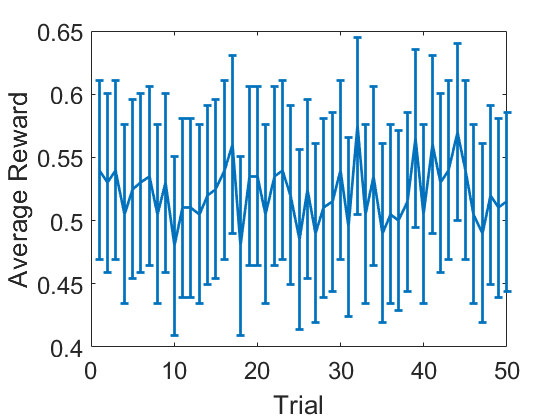

for j = 1:1:repetitions
    totalRewards(j,:) = monkey_ANN(nTrials,learningRate,epsilon); %simulate one episode and store rewards obtained for each trial in the episode
end
    
% Plot the average reward as a function of the number of trials --> the average has to be performed over the episodes
figure
h2=errorbar(mean(totalRewards),2*std(totalRewards)./sqrt(repetitions)); %errorbars are equal to twice standard error i.e. std/sqrt(samples)
set(h2,'linewidth',2);
xlabel('Trial','fontsize',fontSize);
ylabel('Average Reward','fontsize',fontSize);
set(gca,'fontsize',fontSize);

***Main function (artificial neural network)***

function Rewards = monkey_ANN(nTrials, learningRate, epsilon)
    %States and actions
    Baloon = 1;
    Bicycle = 2;
    
    Red = 1;
    Green = 2;
    
    nStates = 2; %number of states
    nActions = 2; %number of actions
    
    % Define input states as unit vectors to present to the network --> Baloon=(1,0), Bicycle=(0,1)
    states = eye(nStates);
    
    % Weights matrix, connecting input neurons (state) to output neurons (actions). Initially random 
    % Parameters:
    % - nActions = number of output neurons, 
    % - nStates = number of input neurons. 
    weights = rand(nActions,nStates);
    
    % Define reward vector (one position for each trial) and intialise it to zero
    Rewards = zeros(1,nTrials);
    
    % Start the episode
    for trial = 1:nTrials
        
        %Present a picture / state; Ballon=1 Bicycle=2;
        Image = (rand<0.5) + 1; %half times Ballon, half times Bicycle
        
        %Convert the state into a vector
        input = states(:,Image);
        
        %Compute Qvalues. Qvalue=logsig(weights*input). Qvalue is 2x1, one value for each output neuron
        Qvalue = 1./(1+exp(-weights*input)); %implementation of logsig
        
        %Epsilon-greedy parameter
        eGreedy = (rand<epsilon); %with probability epsilon chose action at random; if epsilon=0 then always choose Greedy
        
        %Implement the policy
        if or( (Qvalue(Red,1)==Qvalue(Green,1)), eGreedy)
            Action = (rand<0.5) + 1; %if Qvalues are the same or epsilon>0 (e-Greedy, chose at random with probability epsilon) chose one at random
        else       
            Action = (Qvalue(Green,1)>Qvalue(Red,1)) + 1; %otherwise choose greedy. Will result Action=2 (Green) if Qvalue(Image,Green)>Qvalue(Image,Red) and Action=1 (Red) otherwise (Greedy)            
        end
        
        %Collect reward    
        if and( (Image==Baloon),(Action==Green) )
            r = 1;
        elseif and( (Image==Bicycle),(Action==Red) )
            r = 1;
        else
            r = 0;
        end
        
        %Rectified output - a binary array with a single non-zero element corresponding to the selected action. This is in order to update the weights only to the neuron whose action we selected.
        rectOutput = zeros(2,1);
        rectOutput(Action,1) = 1; 
            
        %TODO: Update weigths
        %weights = ;
        
        %Store reward for the current trial  
        Rewards(1,trial) = r;    
    end   
end